Script to plot the positions and velocities of molecules exiting the beamsource

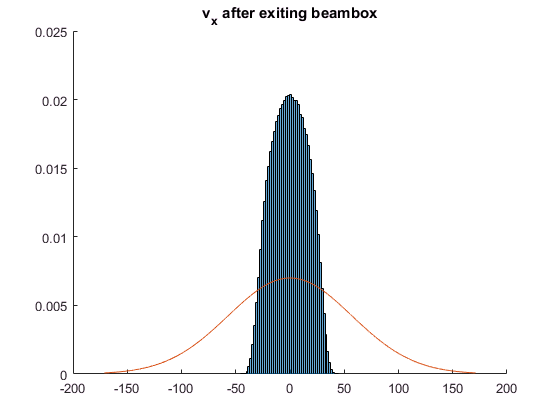

%Load the positions and velocities from a file
load('velocities_after_beamsource_1e8.mat')
load('positions_after_beam_source_1e8.mat')

%Initial distributions for comparison:
beam.v_z = 200; %longitudinal velocity (m/s)
beam.sigma_v_z = 13; %spread in longitudinal velocity (m/s)
beam.v_t = 0; %transverse velocities should be zero on average but with some spread
%beam.sigma_v_x = tan(FWHM/2)/sqrt(2*log(2)) * beam.v_z; %spread in x velocity (m/s)
beam.sigma_v_x = 57; %spread in x velocity (m/s)
beam.sigma_v_y = beam.sigma_v_x; %spread in y velocity (m/s)
beam.sigma_v_t = 27.6; %spread in transverse velocity (m/s)

%PDFs for initial molecule distributions
v_t = (beam.v_t-3*beam.sigma_v_x):0.01:(beam.v_t+3*beam.sigma_v_x);
v_z = (beam.v_z-3*beam.sigma_v_z):0.01:(beam.v_z+3*beam.sigma_v_z);

pdf_v_t = pdf('Normal',v_t,beam.v_t,beam.sigma_v_x);
pdf_v_z = pdf('Normal',v_z,beam.v_z,beam.sigma_v_z);


%Make histograms of velocities:
%X-direction first
figure
hold on
histogram(v_final(:,1),'Normalization','pdf','NumBins',50)
title('v_x after exiting beambox')
plot(v_t, pdf_v_t)
hold off

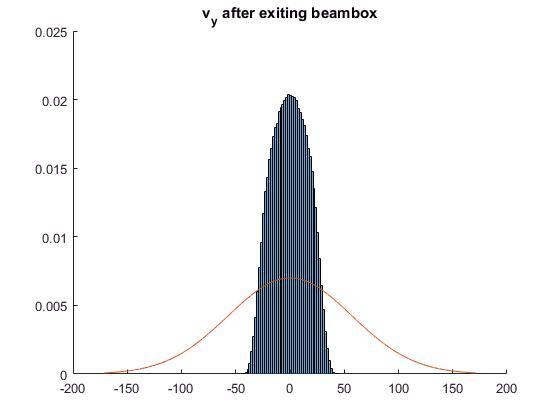

%Velocity in y-direction next
figure
hold on
histogram(v_final(:,2),'Normalization','pdf','NumBins',50)
title('v_y after exiting beambox')
%plot(v_t, pdf_v_t)

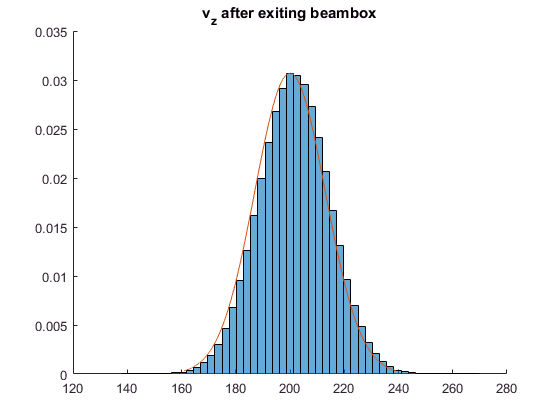


%z-direction
figure
hold on
histogram(v_final(:,3),'Normalization','pdf','NumBins',50)
title('v_z after exiting beambox')
plot(v_z, pdf_v_z)

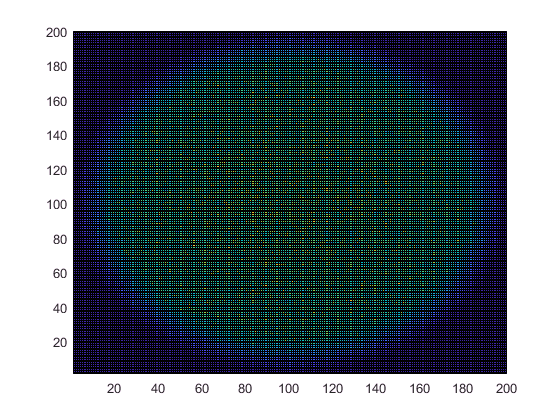


%Plot positions after beam box
figure
n = hist3(x_final(:,[1 2]),'Nbins',[200 200]);
pcolor(n)

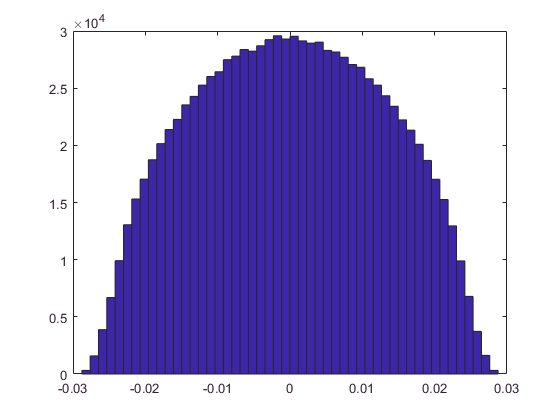

%% x-position individually next
figure
hist(x_final(:,1),50)

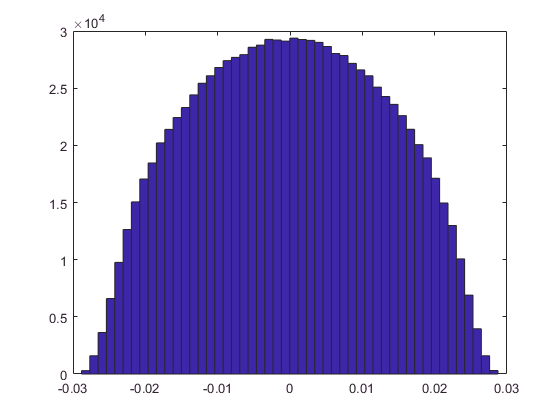

%% x-position individually next
figure
hist(x_final(:,2),50)

%Initial distributions for comparison:


Analytic calculations based on a point source with uniform longitudinal velocity of 200 m/s for comparison.

1st calculate which of the elements within the aperture is the most constraining by calculating angle extended from the zone of freezing:

Calculation: $\Delta \theta ={\mathrm{tan}}^{-1} \left(\frac{\Delta x}{\Delta z}\right)$. Specifying positions in meters.

meters_per_inch = 0.0254; %conversion factor from inches to meters

%zone of freezing is at .25in from aperture
zone_of_freezing.z = .25*meters_per_inch;

%Start of conical collimators:
FourK_collimator.z_1 = 0.325*meters_per_inch; %4K collimator start z position
FourK_collimator.d_1 = 0.232*meters_per_inch; %4K collimator start diameter
FourK_collimator.theta_1 = atan(FourK_collimator.d_1/2/(FourK_collimator.z_1-zone_of_freezing.z))

FourK_collimator = struct with fields:
        z_1: 0.0083
        d_1: 0.0059
    theta_1: 0.9968



FourK_collimator.z_2 = FourK_collimator.z_1 + 1*meters_per_inch; %4K collimator end z position
FourK_collimator.d_2 = 1*meters_per_inch; %4K collimator end diameter
FourK_collimator.theta_2 = atan(FourK_collimator.d_2/2/(FourK_collimator.z_2-zone_of_freezing.z))

FourK_collimator = struct with fields:
        z_1: 0.0083
        d_1: 0.0059
    theta_1: 0.9968
        z_2: 0.0337
        d_2: 0.0254
    theta_2: 0.4354



%4K shield dimensions
FourK_shield.z_1 = FourK_collimator.z_2+ meters_per_inch * 0.375; %4K shield z position
FourK_shield.z_2 = FourK_shield.z_1 + meters_per_inch * 0.25; %4K shield z position
FourK_shield.d_1 = meters_per_inch*1; %4K shield aperture diameter
FourK_shield.d_2 = meters_per_inch*1; %4K shield aperture diameter

FourK_shield.theta = atan(FourK_shield.d_1/2/(FourK_shield.z_1-zone_of_freezing.z))

FourK_shield = struct with fields:
      z_1: 0.0432
      z_2: 0.0495
      d_1: 0.0254
      d_2: 0.0254
    theta: 0.3321



%40K shield dimensions
FortyK_shield.z_1 = FourK_shield.z_2 + meters_per_inch * 1.25; %40K shield z position
FortyK_shield.z_2 = FortyK_shield.z_1 + meters_per_inch * .25; %40K shield z position
FortyK_shield.d_1 = meters_per_inch*1; %40K shield aperture diameter
FortyK_shield.d_2 = meters_per_inch*1; %40K shield aperture diameter

FortyK_shield.theta = atan(FortyK_shield.d_1/2/(FortyK_shield.z_1-zone_of_freezing.z))

FortyK_shield = struct with fields:
      z_1: 0.0813
      z_2: 0.0876
      d_1: 0.0254
      d_2: 0.0254
    theta: 0.1679



%Beam box exit dimensions
BB_exit.z_1 = FortyK_shield.z_2 + meters_per_inch * 2.5; %z position
BB_exit.z_2 = BB_exit.z_1 + meters_per_inch * 0.75; %z position
BB_exit.d_1 = meters_per_inch*4; %diameter of beam box exit
BB_exit.d_2 = BB_exit.d_1; %diameter of beam box exit

BB_exit.theta = atan(BB_exit.d_1/2/(BB_exit.z_1-zone_of_freezing.z))

BB_exit = struct with fields:
      z_1: 0.1511
      z_2: 0.1702
      d_1: 0.1016
      d_2: 0.1016
    theta: 0.3375


So the aperture in the 40K shield is the limiting aperture in terms of angular width of the beam. The angular width of of the velocity distribution is given by $\Delta \theta ={\mathrm{tan}}^{-1} \left(\frac{{\Delta \text{ }v}_T }{v_L }\right)$. For longitudinal velocity of 200 m/s this would limit the width of the transverse velocity to be:

%Calculate Delta_v_t:
Delta_v_t =  tan(FortyK_shield.theta)*200

Delta_v_t = 33.8983

This value agrees well with what is seen in the numerical simulations for the extedned source which acts a good sanity check for the simulations. The spreading out of the distriibution in the numerical simulations is due to the source being extended.

Now calculate correlations between the velocities and positions to check if it would still be a good approximation to get positions and velocities from independent velocity distributions:

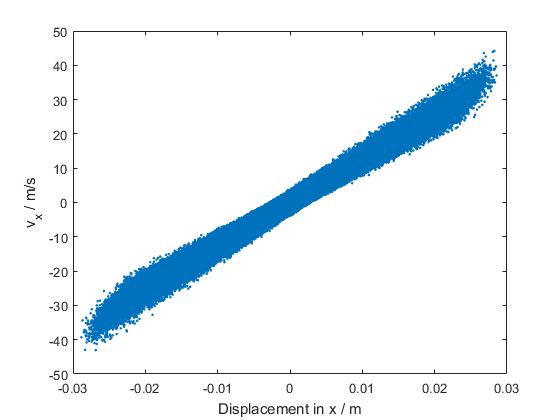

figure
plot(x_final(:,1),v_final(:,1),'.')
xlabel('Displacement in x / m')
ylabel('v_x / m/s')

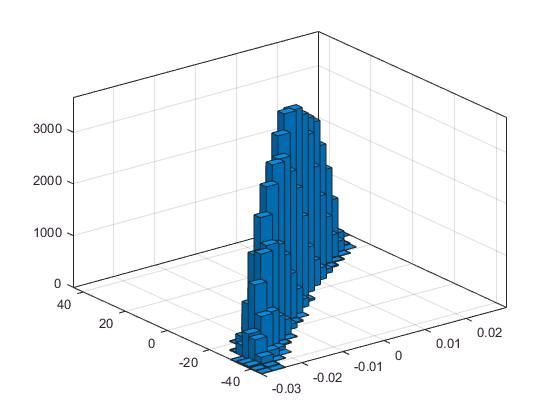

figure
histogram2(x_final(:,1),v_final(:,1))

There clearly is a correlation between the x-position outside the beam source and the x-velocity. Therefore we'll need to use some kind of 2D probablity density function to get a pair of x and v_x for a molecule (or just use the trajectories saved into file). Now just check that the x-position and the velocities in other directions are not correlated:

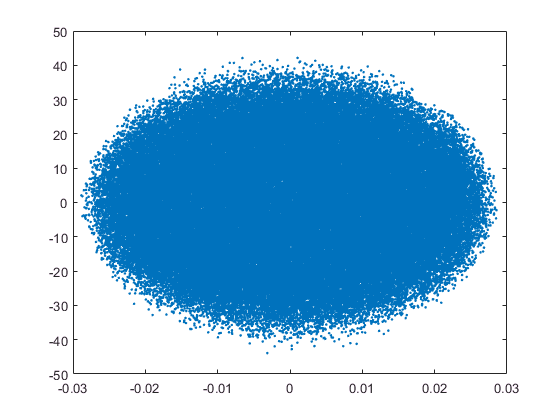

%Y-direction first:
figure
plot(x_final(:,1),v_final(:,2),'.')

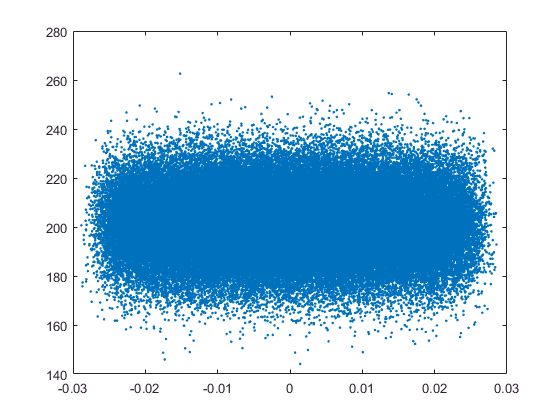

%and z-direction next:
figure
plot(x_final(:,1),v_final(:,3),'.')

Can also calculate the correlation matrix to check:

%Get velocities and positions into the same matrix
M = [x_final v_final];
[R,P] = corrcoef(M)

R =     1.0000    0.0035   -0.0000    0.9916    0.0042   -0.0032
    0.0035    1.0000   -0.0000    0.0039    0.9917    0.0083
   -0.0000   -0.0000    1.0000   -0.0000    0.0000    0.0000
    0.9916    0.0039   -0.0000    1.0000    0.0046   -0.0025
    0.0042    0.9917    0.0000    0.0046    1.0000    0.0080
   -0.0032    0.0083    0.0000   -0.0025    0.0080    1.0000


P =     1.0000    0.2661    1.0000         0    0.1829    0.3111
    0.2661    1.0000    1.0000    0.2185         0    0.0084
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
         0    0.2185    1.0000    1.0000    0.1422    0.4205
    0.1829         0    1.0000    0.1422    1.0000    0.0106
    0.3111    0.0084    1.0000    0.4205    0.0106    1.0000


There is no correlation between the x-and y- directions per se, but the the radial position of the molecules must always be such that the radial position is less than some limitiing value, and the radial velocity also must be such that the molecule trjectory fits through the smallest aperture. Thus the x- and y-parts of the trajectories are in fact not independent. It would therefore seem reasonable to start using cylindrical coordinates (duh).

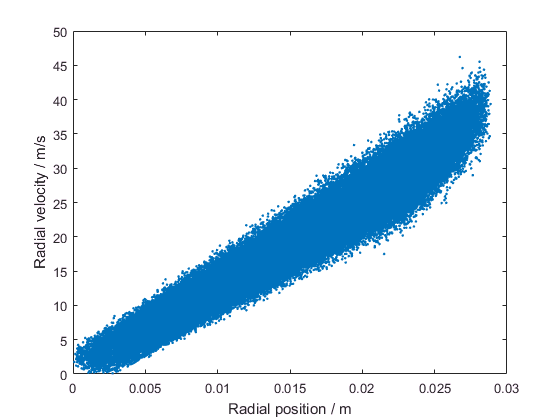

%Get matrices of radial positions and velocities at the end:
r = (x_final(:,1).^2+x_final(:,2).^2).^(1/2);
v_r = (v_final(:,1).^2+v_final(:,2).^2).^(1/2);

%Plot to see correlation
figure
plot(r,v_r,'.')
xlabel('Radial position / m')
ylabel('Radial velocity / m/s')

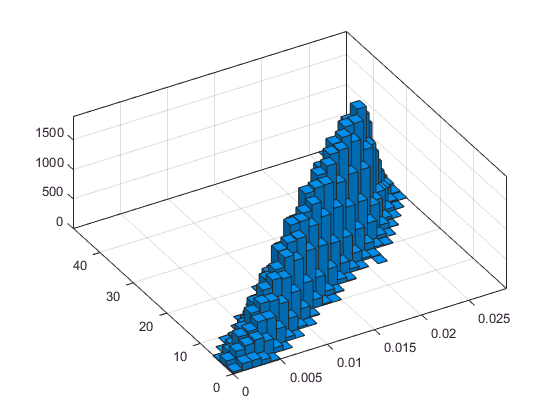

figure
histogram2(r,v_r)

Check if the molecules are uniformly distributed in theta:

%Theta = 